### **Set up parameters**

        Set up accessibility range for simulation 

        set region of heatmap for comparison 

acc_range = linspace(0,1,101);

lb = 1;
rb = num_pix_y*aspt_ratio;

### Calculate Nucleoid Volume Ratio

% static simulation
[nuc_volume_ratio,cmp_acc_htMap] =...
    Nuc_acc(2e6,acc_range,Ro,Lo,anchor_spMap,...
    scaling_width,scaling_length,num_pix_y,aspt_ratio,...
    2*height(raw_heatmap),'off');

Nucleoid Volume Ratio = 0.0827 (N = 2000000)


### Calculate Nucleoid Accessibility

        Use 'SSIM' metric for similarity quantificaiton 

Metric_optz = htMap_similarity(htMap,cmp_acc_htMap,...
    acc_range,lb,rb,'off');
% Get accessibility from similarity quantification
acc_fit = AccFit(acc_range,Metric_optz,'SSIM');

Nucleoid Accessibility = 0.6000


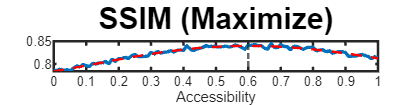

SaveFigure(result_folder,'Accessibility Metric',...
    gcf, {'fig','png','svg'},'jet')

### Distance Map (error pixelwise)

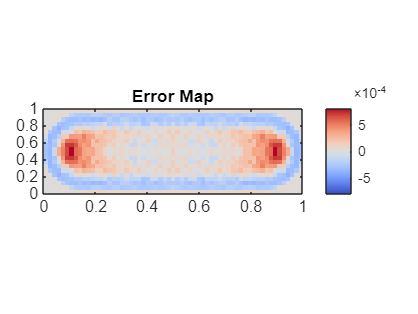

figure
% error map: exp - simu_optimal
[~, accidx] = min(abs(acc_range - acc_fit));
clr = max(max((htMap-cmp_acc_htMap{accidx}),[],'all'),...
          abs(min((htMap-cmp_acc_htMap{accidx}),[],'all')));
fig_htMap((htMap-cmp_acc_htMap{accidx}),num_pix_y,aspt_ratio,slanCM('coolwarm'),'on',[-clr, clr])
title('Error Map')
clear accidx clr

SaveFigure(result_folder,'Error Heatmap',...
    gcf, {'fig','png','svg'},slanCM('coolwarm'))

### Heatmap comparision 

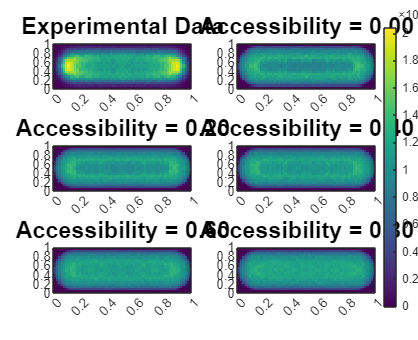

% Show simulated htMap with different accessibility 
% for comparison with experimental data
figure
fig_cmp_htMap(htMap,cmp_acc_htMap,acc_range,(0:0.2:0.8),...
    num_pix_y,aspt_ratio,slanCM('viridis'),true,[])
SaveFigure(result_folder,'Acc Heatmap Comparison',...
    gcf, {'fig','png','svg'},slanCM('viridis'))